Question 2.1

b)

%data = readmatrix('log_2026-03-03_11-05-11.csv');
data_b = readtable('log/log_2026-03-03_11-05-11.csv', VariableNamingRule='preserve')

data_b = 17789×14 table
    timestamp [s]    actual_current [A]    target_current [A]    timestep [us]    motor_torque [N.m]    encoder_paddle_pos [deg]    hall_voltage [V]    spring constant    zero_angle    relative_angle    led_0 [0.0-1.0]    led_1 [0.0-1.0]    led_2 [0.0-1.0]    led_3 [0.0-1.0]
    _____________    __________________    __________________    _____________    __________________    ________________________    ________________    _______________    __________    ______________    _______________    _______________    _________

hall_voltage = data_b.("hall_voltage [V]"); 
std_values = std(hall_voltage)

std_values = 0.0940

c)

data_c = readtable('log/log_2026-03-03_12-09-43.csv', VariableNamingRule='preserve')

data_c = 73955×14 table
    timestamp [s]    actual_current [A]    target_current [A]    timestep [us]    motor_torque [N.m]    encoder_paddle_pos [deg]    hall_voltage [V]    spring constant    zero_angle    relative_angle    led_0 [0.0-1.0]    led_1 [0.0-1.0]    led_2 [0.0-1.0]    led_3 [0.0-1.0]
    _____________    __________________    __________________    _____________    __________________    ________________________    ________________    _______________    __________    ______________    _______________    _______________    _________

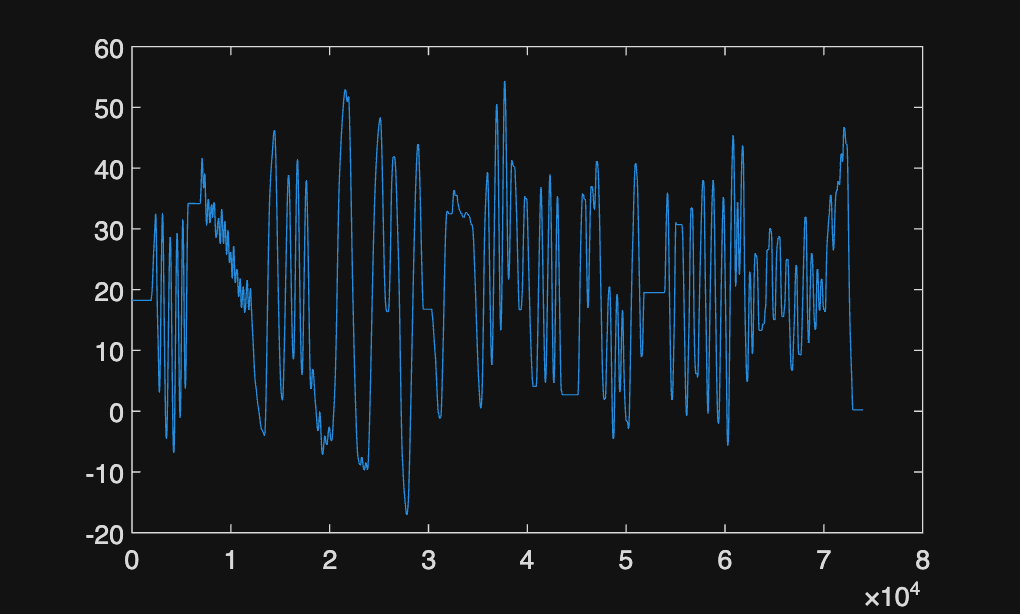

hall_voltage_c = data_c.("hall_voltage [V]");
angle_c = data_c.("encoder_paddle_pos [deg]"); 
plot(angle_c)



p = polyfit(hall_voltage_c, angle_c, 1);
m = p(1) % Slope (Sensitivity in Degrees/Volt)

m = 48.7132

c = p(2) % Intercept (Offset)

c = -96.7068



fprintf('Characteristic Function: Angle = %.6f * V + %.6f\n', m, c);

Characteristic Function: Angle = 48.713203 * V + -96.706816



fprintf('Characteristic Function: Angle = %.4f * V + %.4f\n', m, c);

Characteristic Function: Angle = 48.7132 * V + -96.7068


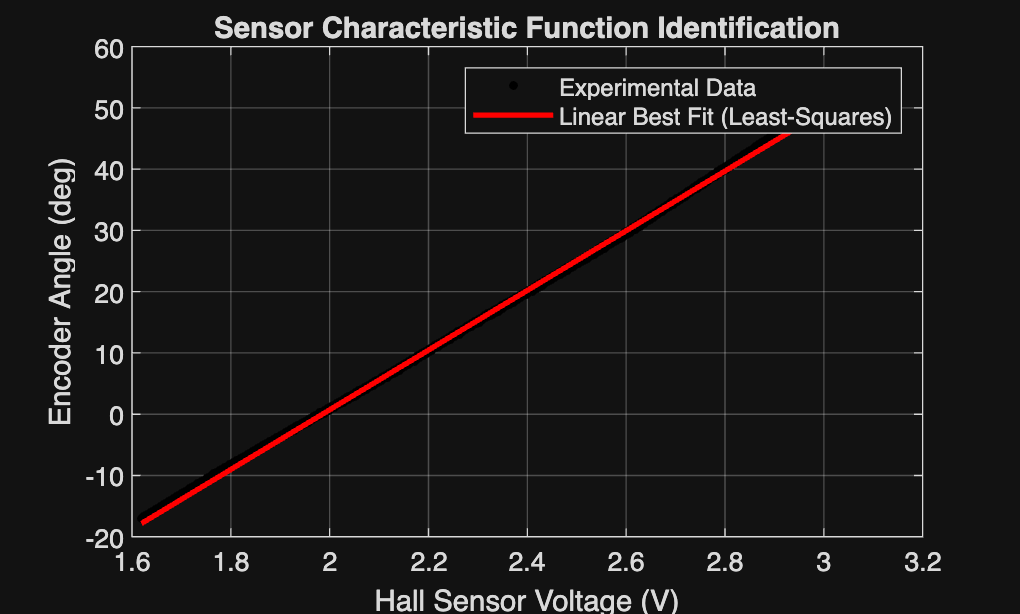

% --------------------------------------------------------------------

% --------------------- Visualization --------------------------
figure;
plot(hall_voltage_c, angle_c, 'k.', 'MarkerSize', 10); hold on;
grid on;
fplot(@(x) m*x + c, [min(hall_voltage_c) max(hall_voltage_c)], 'r', 'LineWidth', 2);

xlabel('Hall Sensor Voltage (V)');
ylabel('Encoder Angle (deg)');
title('Sensor Characteristic Function Identification');
legend('Experimental Data', 'Linear Best Fit (Least-Squares)');

Noé